# Evaluating the Edge based Spatial Frequency Response (e-TF, Edge based Transfer Function)

## Overview of Measurement Methods for the OTF

Measuring the OTF of an optical system can be done in several ways:

- Interferometric measurement of the wavefront in the exit pupil. This can be very accurate, but it is very complex and costly. It uses coherent light.

- Imaging a point source and measure the PSF. However, if the incoherent response is seeked for, a point source is a difficult undertaking. Additionally, the PSF is typically in the dimension of a pixel of image sensors, so a direct measurement is most often not possible. A magnifying microscope is needed. The calibration is then getting complex.

- Using the USAF target, i.e. seperate spatial frequencies. This is a easy way, however, only a few measurment points (contrast values) are generated. Additionally, the frequencies are not located at the same location, which can cause unwanted effects. If the frequencies are shifted to the same location, the measurement takes a lot of time. Whereas for the direct measurement of the OTF sine-patterns with infinite extend are ideally required, the USAF target consist of space limited rect-functions. This causes artifacts that can not always corrected for.

- Analysing the image of an edge. This has the advantage, that an edge is easy to manufacture. As for imaging a point source, the image of the edge transition is in the order of the pixel of image sensors, thus a direct measurment is often not appropriate. However, there is a 'trick': The edge is slightly slanted. As each row of the image is slightly shifted, taken rows in an appropriate way together, a profile with much higher resolution can be generated and than be evaluated. This method is called the slanted edge method and is standardized in ISO 12233:2014. It has the advantage that the measurement is done in one shot and a range of relevant spatial frequencies is measured. As with the other methods above (except the interferometric measurement), the response of the system, consisting of the optical lens and the image sensor, is measured. As the image sensor has a low pass characteristic, getting the pure OTF is only possible for lower frequencies and if the sensors response is known.

## E-SFR / e-TF Theoretical Background

From the systems PSF the edge spread function ESF is determined via


$$ESF(x')=\int\limits_{-\infty}^{x'} \int\limits_{-\infty}^{\infty} PSF(x'',y'') \text{d} y'' \text{d} x''$$


The differentiation of the ESF yields the line spread function LSF:


$$LSF(x')=\frac{\delta }{\delta x'} ESF(x') = \int\limits_{-\infty}^{\infty} PSF(x',y'') \text{d} y'' $$


The 1D-Fourier transform of the LSF results in the edge based transfer Function e-TF (which is called in the standard the edge based spatial frequency response e-SFR):


$$e\!-\!TF(u')=\int\limits_{-\infty}^{\infty} LSF(x') e^{j2\pi\cdot x' \cdot u'} \text{d} x' = \int\limits_{-\infty}^{\infty} \int\limits_{-\infty}^{\infty} PSF(x',y'') \text{d} y'' e^{j2\pi\cdot x' \cdot u'}  \text{d} x'  = OTF(u',v'=0) $$


Therefore the 1D-FT of the differentiated edge profile yields the system OTF accross the edge.

The rows of the slanted edge profile are projected along the edge. This results in a supersampled projected profile, i.e. a finer sampling than with just one row. However the sampling is nonaquidistant and has to be converted in a supersampled aquidistant sampling in order that the DFT can be applied (in the standard, this is just done by averaging, but other methods like interpolation or weighted averaging could be used). This supersampling (smaller $\Delta x'$) allows for a higher maximal spatial frequency of the DFT ($u'_{max}=1/\Delta x'/2$), thus may avoid aliasing artifacts. This is relevant in most practical cases where the sampling of the image sensor violates the Nyquist criterium (the pixels are to big for the adequat sampling of the optical irradiance profile).

## E-SFR / e-TF Procedure

As above mentioned evaluating the e-SFR is based on imaging a slightly slanted edge.

## Load an imge

% Set path to image file
p=strsplit(userpath,'\'); p=strjoin(p(1:end-1),'\');
p =[p '\VL\Optische Systeme\Matlab\'];
if 1 % with microscope
    filename='3 - ESFR_5°_microscope_w0_2group.bmp';
    m_measure=5.0; % magnification of microscope
    roi=[309 217 23 74];
else % without microscope
    filename='10 - ESFR_5°_w0_2group.bmp';
    m_measure=1.0; % magnification without microscope
    roi=[302 201 19 66];
end
a = double(imread([p filename])); 

Extract region of interest

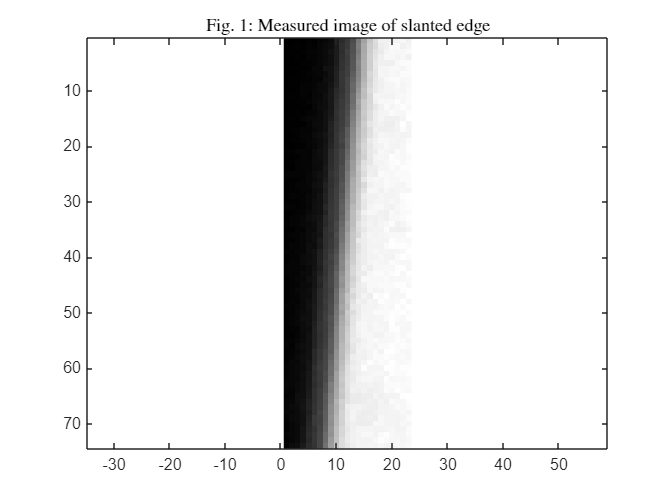

a=double(a(roi(2):roi(2)+roi(4)-1,roi(1):roi(1)+roi(3)-1));
[N_lin N_pix] = size(a); %number of lines and pixels

figure
imagesc(a); colormap(gray), axis equal 
title(['Fig. ' num2str(get(gcf,'Number')) ': Measured image of slanted edge'],'Interpreter','Latex')

## Find subpixel edge locations in each row

The subpixel edge location based on the Canny-method is done in the following steps:

- Filter the edge profile by a Gaussian (choose length of Gaussian kernel $N_{Gauss}$ and $\sigma$of Gaussian appropriately)

- Calulate the derivative of the filtered profile

- Find the extremum in the derivative

- Use the right and left neighbour pixels of the extremum and find the maximum of the parabola going through these three points (aquivalent to this is using the derivative of these three points and calculate the zero-crossing of the line through the two derivative points)

sigma=1.7; % sigma of Gaussian
N_Gauss=2*ceil(2*sigma)+1; % length of the kernel (odd)
Gauss=fspecial('gaussian',[1 N_Gauss],sigma); % Gaussian kernel
pix_pos=(1:N_pix); % pixel positions
for i=1:N_lin
    pix_val_canny=conv(a(i,:),Gauss,'valid'); % filtering the profile
    pix_val_canny_der=diff(pix_val_canny); % derivative of profile
    [max_pix,ind_max]=max(abs(pix_val_canny_der)); % extremum of profile
    if ind_max==1 | ind_max==length(pix_val_canny_der), error('max at edge: ROI too small'), end % check if extremum is at the edge of the profile
    pix_der2_sel=diff(pix_val_canny_der([ind_max-1 ind_max ind_max+1])); % calculate 2nd derivative
    if prod(pix_der2_sel) >0, error('Not a central maximum for CANNY'); end
    loc(i)=pix_pos(ind_max-1+(N_Gauss-1)/2)+(1-pix_der2_sel(1)/diff(pix_der2_sel)); % calculate zero crossing
end
line(loc,1:N_lin,'Marker','.','LineStyle','none', 'color','r')

## Fit a line to the edge locations and determine angle of that line

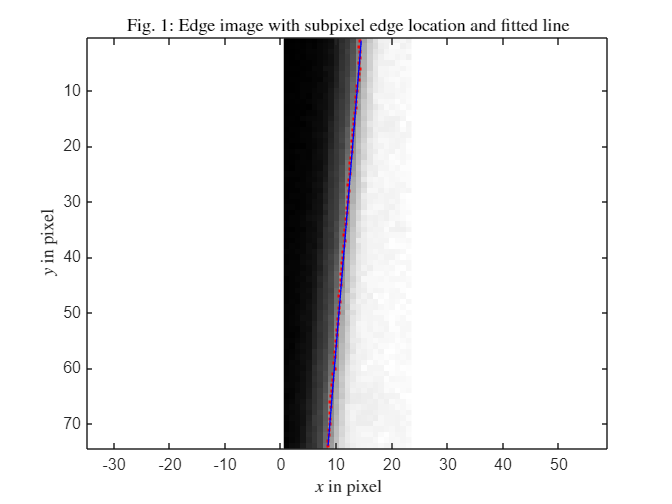

p_line = polyfit(1:N_lin, loc,1); 
line(p_line(1)*(1:N_lin)+p_line(2),1:N_lin,'color','b')
title(['Fig. ' num2str(get(gcf,'Number')) ': Edge image with subpixel edge location and fitted line'],'Interpreter','Latex')
xlabel('$x$ in pixel','Interpreter','Latex'), ylabel('$y$ in pixel','Interpreter','Latex')

disp(['Slope angle of edge: ' num2str(180*atan(abs(p_line(1)))/pi) '°'])

Slope angle of edge: 4.6818°


## Project the profiles along the direction of the edge (i.e. the fitted line)

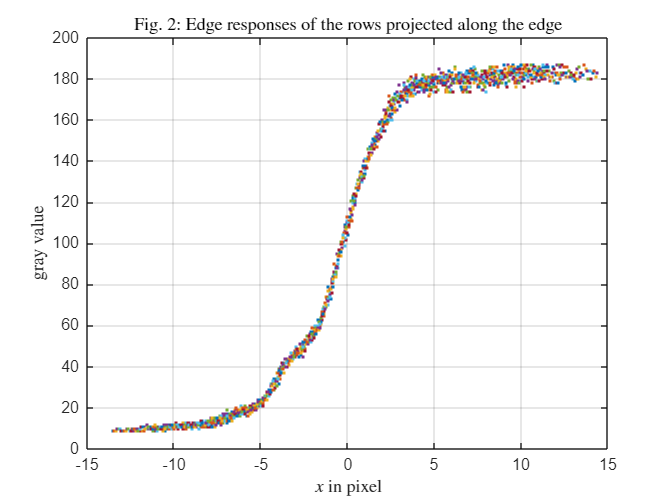

pos_project_lin=repmat((0:N_lin-1)'*sin(atan(-p_line(1))),1,N_pix); % positions of the projected profiles
offset_project=-((1:N_pix) - p_line(2))*cos(atan(p_line(1))); % offset of the projected profiles

x=pos_project_lin-repmat(offset_project,N_lin,1); % x-coorinates of each row after projection

figure
plot(x',a','Marker','.','LineStyle','none')
grid on
title(['Fig. ' num2str(get(gcf,'Number')) ': Edge responses of the rows projected along the edge'],'Interpreter','Latex')
xlabel('$x$ in pixel','Interpreter','Latex'), ylabel('gray value','Interpreter','Latex')

## Average the non-aquidistant, high resolution profile in bins 4 times smaller than the original pixels of the image

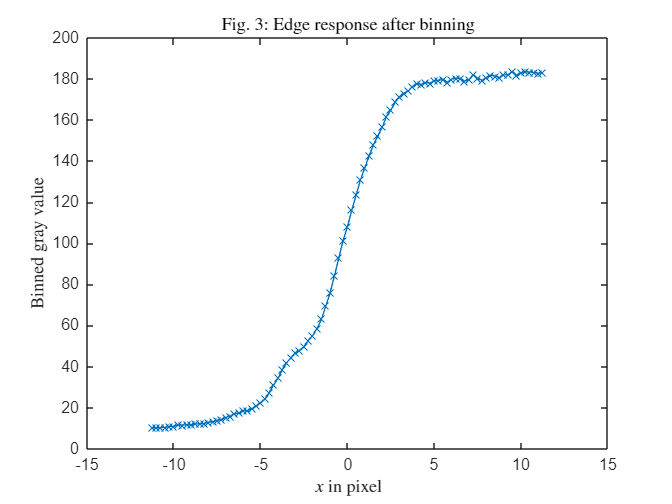

nbin=4; % Binned pixels are 4 times smaller than  original pixels, according to standard

dx_bin=1/nbin;
N_esf_bin=floor(N_pix*cos(atan(p_line(1)))/dx_bin); % number of bins
x_edg=-N_esf_bin*dx_bin/2:dx_bin:N_esf_bin*dx_bin/2; % edges of bins

[bincounts,ind]= histc(x(:),x_edg);
esf_bin=zeros(1,N_esf_bin);
for i=1:N_esf_bin
    if bincounts(i)
        esf_bin(i)=sum(a(ind==i))/bincounts(i);
    end
end
x_esf_c=(x_edg(1:N_esf_bin)+x_edg(2:N_esf_bin+1))/2;

figure
plot(x_esf_c,esf_bin, 'Marker','x')
title(['Fig. ' num2str(get(gcf,'Number')) ': Edge response after binning'],'Interpreter','Latex')
xlabel('$x$ in pixel','Interpreter','Latex'), ylabel('Binned gray value','Interpreter','Latex')

## Differentiate the binned profile and calulate e-TF based on DFT

lsf_bin=diff(esf_bin);
N_lsf_bin=N_esf_bin-1; % N_psf_bin even 
x_lsf_c=(x_esf_c(1:end-1)+x_esf_c(2:end))/2; % center of bins

The standard requires to apply a windowing function. However, this causes a broadening of the OTF and thus wrong quantitive results. A window would be adequate if the original edge image shows different brightness gradients in the dark area than in the bright area (this would cause a discontinuity in the replicated lsf-signal and thus crosstalk from higher frequencies). In standard measurement situations such a brightness gradient can be avoided, thus it is here not applied.

%lsf_bin = ahamming(N_lsf_bin,N_lsf_bin/2).*lsf_bin; % windowing of the lsf (default of in standard, however yields wrong quantitative results

Cacluate the 1D-DFT and scale the result

etf_bin = fftshift(fft(ifftshift(lsf_bin)));
etf_bin = etf_bin/sum(lsf_bin);

Correct e-TF for response of the diff -FIR filter (length of 2 pixels)

if mod(N_lsf_bin,2) == 0
    corr=1./sinc((-(N_lsf_bin/2):1:(N_lsf_bin/2-1))/N_lsf_bin);
else
    corr=1./sinc((-(N_lsf_bin-1)/2:1:(N_lsf_bin-1)/2)/N_lsf_bin);
end
corr(abs(corr)>10)=10*sign(corr(abs(corr)>10)); %limit corr to max. of 10

etf=etf_bin(:)'.*corr(:)';

Calculate spatial frequencies based on pixel width:

h_pp=0.00465; % pixel pitch in mm
c_ff=1.0; % Fill factor (area)
h_pix=sqrt(c_ff)*h_pp;

du_q=1/(h_pp*dx_bin)/N_lsf_bin; % spatial frequency sampling
if mod(N_lsf_bin,2) == 0
    u_bin=(-(N_lsf_bin/2):1:(N_lsf_bin/2-1))*du_q;
    u_bin_pos=u_bin(N_lsf_bin/2+1:end);
    etf_pos=abs(etf(N_lsf_bin/2+1:end));
else
    u_bin=(-(N_lsf_bin-1)/2:1:(N_lsf_bin-1)/2)*du_q;
    u_bin_pos=u_bin((N_lsf_bin-1)/2+1:end);
    etf_pos=abs(etf((N_lsf_bin-1)/2+1:end));
end

Calculate optical response by correcting for the sensor response (pixel sampling). A homogenous, rectangular sensitivity of the pixels are assumed, thus the pure sensor response is a sinc-funktion.

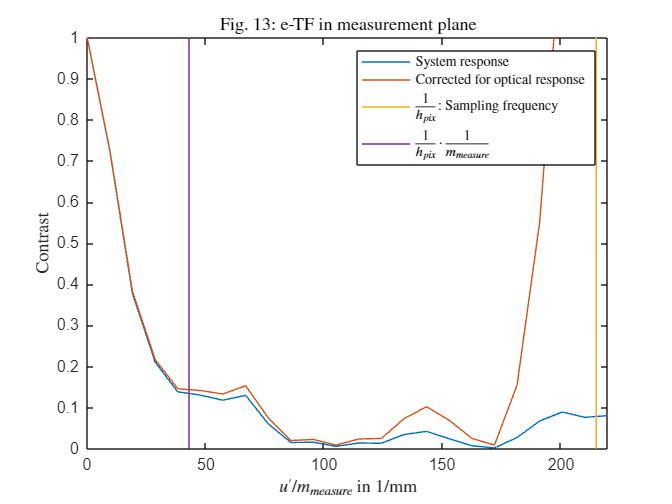

etf_pos_optical=abs(etf_pos./sinc(u_bin_pos*h_pix));

ind_u_max=find(u_bin_pos*h_pix > 1,1,'first');
if isempty(ind_u_max), ind_u_max=length(u_bin_pos); end

figure
plot(u_bin_pos(1:ind_u_max), etf_pos(1:ind_u_max), u_bin_pos(1:ind_u_max), etf_pos_optical(1:ind_u_max),[1 1]/h_pix, [0 1], [1 1]/h_pix/m_measure, [0 1])
title(['Fig. ' num2str(get(gcf,'Number')) ': e-TF in measurement plane'],'Interpreter','Latex')
xlabel('$u''/m_{measure}$ in 1/mm','Interpreter','Latex'), ylabel('Contrast','Interpreter','Latex')
legend({'System response', 'Corrected for optical response','$\frac{1}{h_{pix}}$: Sampling frequency','$\frac{1}{h_{pix}} \cdot \frac{1}{m_{measure}}$'},'Interpreter','Latex')
ylim([0 1]), xlim([0 220])

xlim([0 220])
ylim([0.000 1.000])
zlim([-1.00 1.00])
title("Fig. 13: e-TF in measurement plane", "Interpreter", "latex")

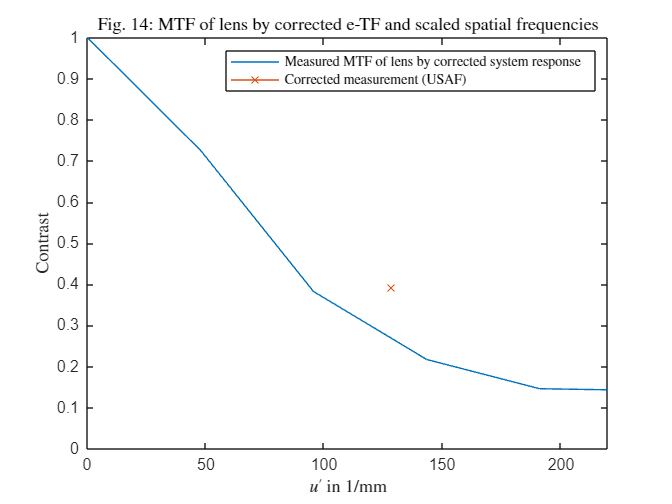

% hold on
% line(36*250/44, 0.5/(4/pi), 'Marker','x') % Corrected measurement (USAF)
if m_measure~=1
    figure
    plot( u_bin_pos(1:ind_u_max)*m_measure, etf_pos_optical(1:ind_u_max))
    line(22.62*250/44, 0.5/(4/pi), 'Marker','x') % Corrected measurement (USAF)
    title(['Fig. ' num2str(get(gcf,'Number')) ': MTF of lens by corrected e-TF and scaled spatial frequencies'],'Interpreter','Latex')
    xlabel('$u''$ in 1/mm','Interpreter','Latex'), ylabel('Contrast','Interpreter','Latex')
    legend({'Measured MTF of lens by corrected system response','Corrected measurement (USAF)'},'Interpreter','Latex')
    ylim([0 1]), xlim([0 220])
end
title("Fig. 14: MTF of lens by corrected e-TF and scaled spatial frequencies", "Interpreter", "latex")